# Control and Instrumentation Lab Assignment 2

**SWARNENDU PAUL 19EE3FP18**

**Question 6**

For a dc series connected LR circuit we know,


$$V = IR + L\frac{dI}{dt}$$
 

if initial current is $I(0)$ then we know current at time = $t$ will be

$I(t) = I(0)e^{-\frac{Rt}{L}} + \frac{V}{R}(1-e^{-\frac{Rt}{L}})$ amp

Given values are,


$$V=1 Volt$$
 
$$R = 0.5\Omega$$
  
$$L=1H$$


So, the given ODE is,

$\frac{dI(t)}{dt} = 1 - 0.5I(t)$ which we need to solve for I(0) = 0 amp and 3 amp.

We will solve this for the interval [0,20s] using RK4 method with h=0.01 

The ODE function is saved as LRCircuit.m 

Now using RK4 method(h=0.01) for I(0)=0 amp

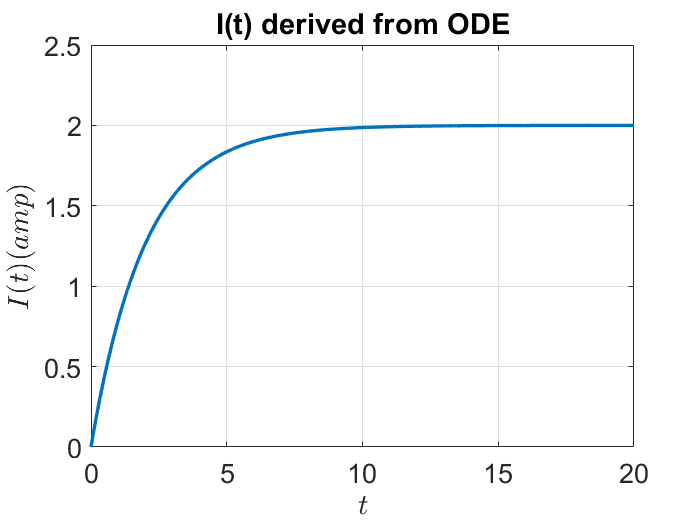

[t,I]=RK4_sol(@LRCircuit,0,20,0,0.01);
plot(t,I,"LineWidth",2);
xlabel('$t$','Interpreter',"latex");
ylabel('$I(t) (amp)$','Interpreter',"latex");
grid on
set(gca,'Fontsize',16);
ylim([0 2.5]);
title("I(t) derived from ODE");

Using the function we have derived for I(t) we will plot again.

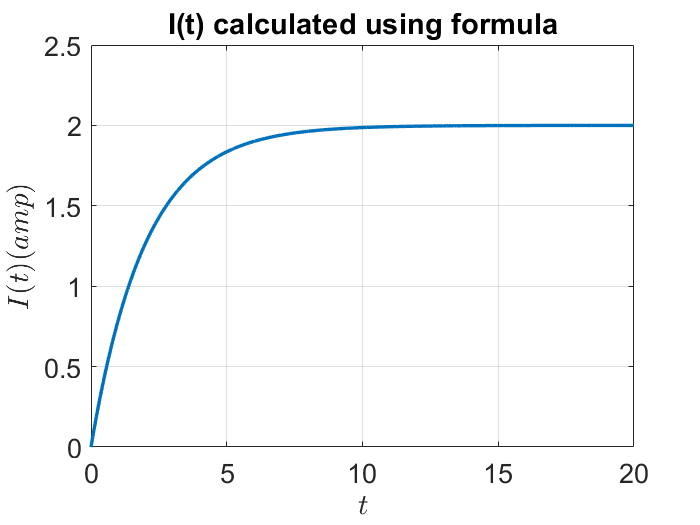

I_real=2.*(1-exp(-0.5.*t));
plot(t,I_real,"LineWidth",2);
xlabel('$t$','Interpreter',"latex");
ylabel('$I(t) (amp)$','Interpreter',"latex");
grid on
set(gca,'Fontsize',16);
ylim([0 2.5]);
title("I(t) calculated using formula");

Now, we can measure accuracy using the norm function.

norm(I-I_real)

ans = 7.3963e-11

which is of the order $10^{-11}$, which is negligible.

Now we will do the same operation for I(0) = 3 amp

RK4 method(h=0.01)

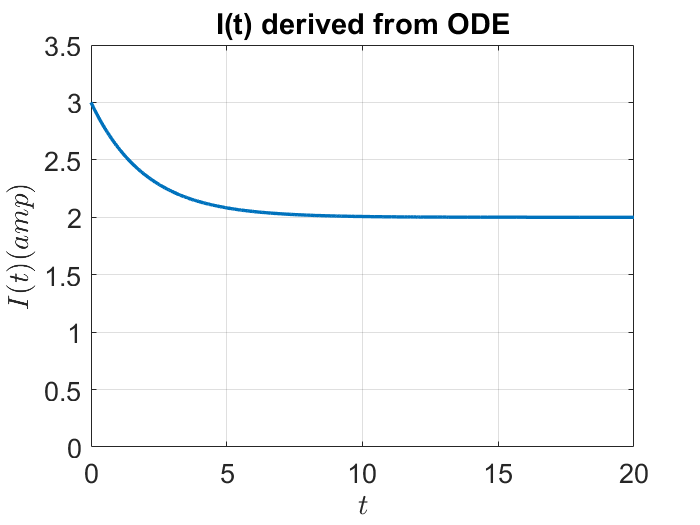

[t,I1]=RK4_sol(@LRCircuit,0,20,3,0.01);
plot(t,I1,"LineWidth",2);
xlabel('$t$','Interpreter',"latex");
ylabel('$I(t) (amp)$','Interpreter',"latex");
grid on
set(gca,'Fontsize',16);
ylim([0 3.5]);
title("I(t) derived from ODE");

Using the function we have derived for I(t) we will plot again.

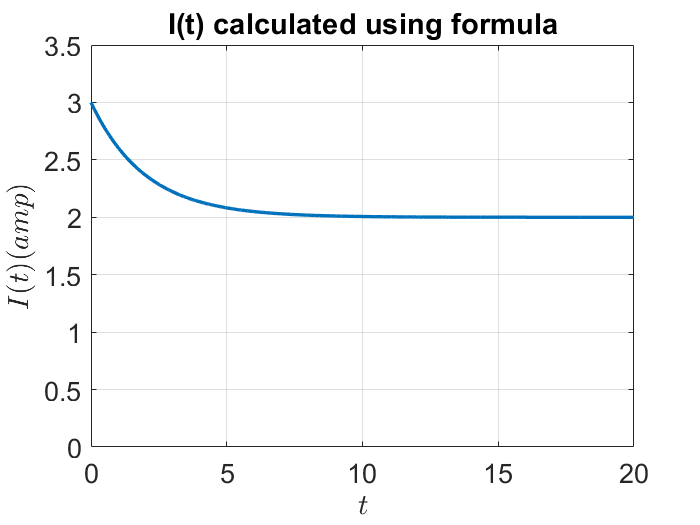

I1_real=3.*exp(-0.5.*t)+2.*(1-exp(-0.5.*t));
plot(t,I1_real,"LineWidth",2);
xlabel('$t$','Interpreter',"latex");
ylabel('$I(t) (amp)$','Interpreter',"latex");
grid on
set(gca,'Fontsize',16);
ylim([0 3.5]);
title("I(t) calculated using formula");

Now, we can measure accuracy using the norm function.

norm(I1-I1_real)

ans = 3.6992e-11

which is of the order $10^{-11}$, so it is negligible.

**Hence,the result matches theoretical predictions.**